# Figure S1H

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A019_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'siCtrl DMSO' }    {[1 2 3 4]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCtrl TAK ' }    {[5 6 7 8]}    {[2]}    {[1]}    {[0 0 0]}
    {'siRif1 DMSO' }    {[1 2 3 4]}    {[3]}    {[1]}    {[0 0 0]}
    {'siRif1 TAK ' }    {[5 6 7 8]}    {[3]}    {[1]}    {[0 0 0]}
    {'siAurkA DMSO'}    {[1 2 3 4]}    {[4]}    {[1]}    {[0 0 0]}
    {'siAurkA TAK '}    {[5 6 7 8]}    {[4]}    {[1]}    {[0 0 0]}
    {'siAurkB DMSO'}    {[1 2 3 4]}    {[5]}    {[1]}    {[0 0 0]}
    {'siAurkB TAK '}    {[5 6 7 8]}    {[5]}    {[1]}    {[0 0 0]}
    {'siPlk1 DMSO' }    {[1 2 3 4]}    {[6]}    {[1]}    {[0 0 0]}
    {'siPlk1 TAK ' }    {[5 6 7 8]}    {[6]}    {[1]}    {[0 0 0]}
    {'siEmi1 DMSO' }    {[1 2 3 4]}    {[7]}    {[1]}    {[0 0 0]}
    {'siEmi1 TAK ' }    {[5 6 7 8]}    {[7]}    {[1]}    {[0 0 0]}
    {'siFoxM1 DMSO'}    {[1 2 3 4]}    {[8]}    {[1]}    {[0 0 0]}
    {'siFoxM1 TAK '}    {[5 6 7 8]}    {[8]}    {[1]}    {[0 0 0]}
    {'siCks1 DMSO' }    {[1 2 3 4


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,3) + round(4*framesPerHr) <= numFrames 
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,3) + round(4* framesPerHr)) < .5 ;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

CRL activation post mitosis

timeGate = [0 20];
cols =  [0 0 .5;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];



**Plot traces aligne****d**

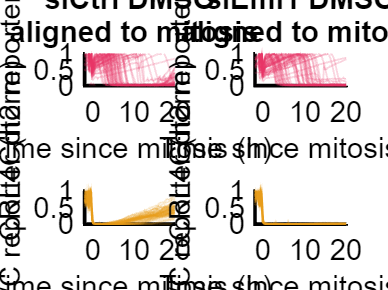

conds=[1 11];
% rng(1)
poiAlign = [ 1];
alignNames = {'mitosis', 'CRL on'};
xlimits = {[-2 20],[-5 5],[-6 8]};
cell_id = [];
for p = 1:length(poiAlign)
   f1 = figure('unit','inches','position',[0 0 4 3]);
   hold on
    for i=1:length(conds)
       inds = ~isnan(S(conds(i)).POI(:,poiAlign(p))) & S(conds(i)).POI_realtime(:,1)>1 & S(conds(i)).apcExpressGate &  S(conds(i)).crlGate & ~isnan(S(conds(i)).POI(:,3));
    
    if conds(i) == 11
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end

        cells = find(inds);
 cell_count = 0;
 
        for numcell = randsample(cells,min([50 length(cells)]))'
            cell_count = cell_count +1;

           cell_id(cell_count,i) = numcell;

            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
                 
             subplot(2,length(conds),i),hold on
                  patchline(timeAligned,S(conds(i)).crlNormAct(numcell,:),...
                    'linewidth',1,'edgealpha',0.2,'edgecolor',[.9 .2 .4]);
                  title({conditions{conds(i),1}, [' aligned to ' alignNames{(p)}]});           
                ylabel('CRL4Cdt2 reporter (norm)');
                xlabel('Time since mitosis (h)');
               ylim([0 1]);
                xlim(xlimits{p});
            
             subplot(2,length(conds),i+length(conds)),hold on
                        patchline(timeAligned,S(conds(i)).apcNormM(numcell,:),...
                    'linewidth',1,'edgealpha',0.2,'edgecolor',[.9 .6 .1]);
                ylabel('APC/C reporter (norm)');
                xlabel('Time since mitosis (h)');
                 ylim([0 1]);
                xlim(xlimits{p});
        

        end
    end
end



%cells in the figure:
% siCtrl  siEmi1
% 9420	2005
% 820	783
% 9180	5471
% 5937	1930
% 3138	1978
% 54	4098
% 8663	5310
% 8738	1917
% 9010	2357
% 6410	141
% 557	4361
% 322	151
% 936	96
% 3367	92
% 8620	76
% 397	4161
% 8829	246
% 3482	4300
% 6098	2187
% 209	301
% 6325	5399
% 914	126
% 400	5613
% 1085	3896
% 3398	189
% 6004	4270
% 3087	4089
% 6171	173
% 2774	2336
% 8928	2077
% 204	140
% 196	4113
% 5985	4285
% 571	2114
% 9550	919
% 2741	3703
% 271	4057
% 2761	412
% 797	204
% 3960	2158
% 1076	2094
% 9538	279
% 3082	272
% 151	2738
% 3961	2203
% 5884	277
% 5930	5549
% 3181	2029
% 987	6218
% 2843	4407

% new: 
% 3548	3851
% 5894	3867
% 269	3639
% 652	199
% 6090	4238
% 8830	5315
% 6387	5310
% 9096	5382
% 3585	2089
% 6658	3761
% 6550	1023
% 8683	3858
% 1107	5480
% 3446	3625
% 8673	2003
% 6417	880
% 2717	2418
% 3922	5616
% 9588	2217
% 6336	5599
% 302	185
% 2811	4098
% 2836	278
% 8847	2178
% 161	5495
% 2727	4482
% 3908	399
% 8737	602
% 5787	2558
% 9007	3768
% 3627	776
% 816	126
% 998	1926
% 3039	1945
% 111	5409
% 787	3780
% 6939	4154
% 3754	3990
% 6530	148
% 454	2336
% 8642	3920
% 499	301
% 6049	5552
% 6755	5632
% 6528	4459
% 6260	3664
% 2876	247
% 2796	2033
% 3367	2138
% 478	246

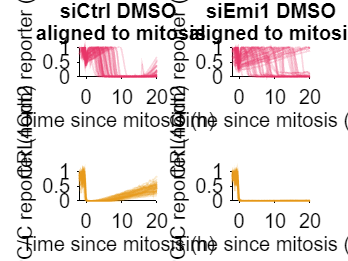

figure (f1)
print_pdf(['fig_S1H.pdf'])